K = 6;
%W = 2000*rand(K,2);
d_min = 100;
T = 210;
H = 100;
NoisePower = 10^(-14);
d0 = 1;
Rho0 = 10^(-6);
Pmax = 0.1;
Vmax = 50;
epsilon = 10^-2;
d_min = 100;
M = 1;
%N = Vmax*T/(H*epsilon);
N = 150;
Tau = 100;
N2 = N*Tau;
%Slot_assignment = Tau * A
deltaT = T/N;
Max_Dist = deltaT * Vmax;

A_init = sol.A;
Q_init = sol2.Q;

A = optimvar('A', K,M,N, 'Type', 'continuous', 'LowerBound', 0, "UpperBound", 1);
Q = optimvar('Q', M,2,N, 'Type', 'continuous', 'LowerBound', 0, 'UpperBound', 2000);


[f, A_sum_k, A_sum_m] = fcn2optimexpr(@UserScheduling, A, P_init, Q_init, K, M, N, Rho0, H, W, NoisePower);
problem = optimproblem('ObjectiveSense', 'max');
problem.Objective = f;


problem.Constraints.cons1 = A_sum_k <= 1;
problem.Constraints.cons2 = A_sum_m <= 1;


x0.A = A_init;

global history;
history.x = [];
history.fval = [];
global stopping;
stopping.x = [];
stopping.fval = [];

show(problem)


  OptimizationProblem : 

	Solve for:
       A

	maximize :
       [argout,~,~] = UserScheduling(A, extraParams{1}, extraParams{2}, 6, 3, 150, 1e-06, 100, extraParams{3}, 1e-14)

       


Solving problem using fmincon.
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0    2701   -1.711627e+00    0.000e+00    1.022e-03


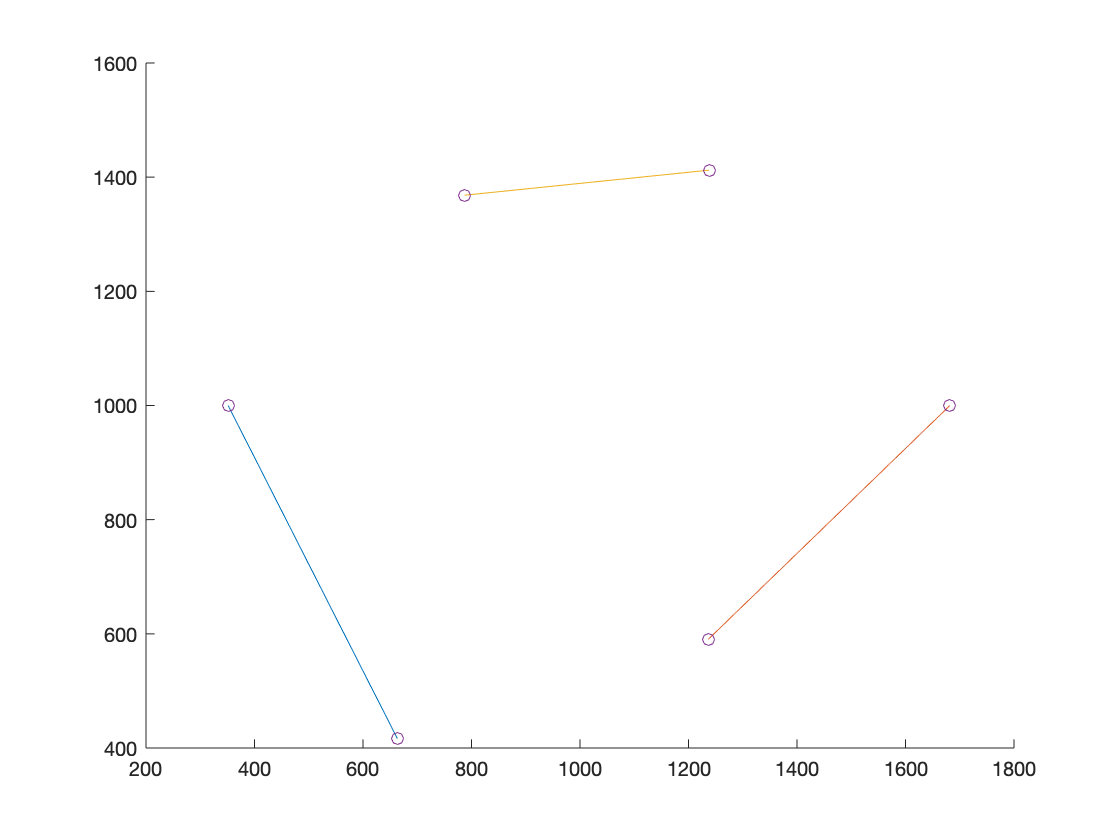

    1    5402   -1.501085e+00    6.240e-02    1.022e-03    4.127e+00
    2    8103   -1.053569e+00    0.000e+00    1.303e-03    5.761e+00
    3   10804   -4.785522e-01    0.000e+00    2.910e-03    7.901e+00
    4   13505   -3.279494e-01    0.000e+00    4.034e-03    2.569e+00
    5   16206   -4.114993e-01    0.000e+00    3.569e-03    1.244e+00
    6   18907   -4.093621e-01    0.000e+00    3.594e-03    4.056e-02
    7   21608   -4.152854e-01    0.000e+00    9.465e-04    6.695e-02
    8   24309   -6.408165e-01    0.000e+00    9.465e-04    2.662e+00
    9   27010   -9.304476e-01    0.000e+00    1.008e-03    3.419e+00
   10   29711   -1.120110e+00    0.000e+00    1.247e-03    2.277e+00
   11   32412   -1.197824e+00    0.000e+00    1.347e-03    1.016e+00
   12   35113   -1.224250e+00    0.000e+00    1.393e-03    5.355e-01
   13   37814   -1.242164e+00    0.000e+00    1.478e-03    4.024e-01
   14   40515   -1.252045e+00    0.000e+00    1.549e-03    2.488e-01
   15   43216   -1.257282e+00    0

options = optimoptions('fmincon', 'OutputFcn',@outfun, 'Display', 'iter', 'MaxFunctionEvaluations', 100000, 'OptimalityTolerance', 1.0000e-04);
[sol, fval, exitflag, output] = solve(problem, x0, 'Options', options);

A_init = sol.A;

global history;
history.x = [];
history.fval = [];
global stopping;
stopping.x = [];
stopping.fval = [];

[f2, speed_constraint, initial_final, inter_uav_distance] = fcn2optimexpr(@TrajectoryOptimization,A_init, P_init, Q, K, M, N, Rho0, H, W, NoisePower, d_min);


problem2 = optimproblem('ObjectiveSense', 'max');
problem2.Objective = f2;


options = optimoptions('fmincon', 'OutputFcn',@outfun, 'Display', 'iter', 'MaxFunctionEvaluations', 50000, 'OptimalityTolerance', 1.0000e-06);

deltaT = T/N;
Max_Dist = deltaT * Vmax

Max_Dist = 70

problem2.Constraints.speed = speed_constraint <= Max_Dist;
problem2.Constraints.repeat = initial_final <= 500;
problem2.Constraints.inter_uav_distance = inter_uav_distance == 1;

x1.Q = Q_init;



Solving problem using fmincon.
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0     901   -1.697104e+00    0.000e+00    1.434e-05



Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


[sol2, fval2, exitflag2, output2] = solve(problem2, x1, 'Options', options);

Q_init = sol2.Q;

Q2 = sol2.Q;

Unable to resolve the name sol2.Q.

Xs = Q2(:, 1, :);
Ys = Q2(:, 2, :);
Xs = reshape(Xs,[M,N]);
Ys = reshape(Ys, [M,N]);
for i = 1:M
    hold on
    plot(Xs(i,:), Ys(i,:));
end
scatter(W(:,1), W(:,2));
hold off
clf

Q3 = Trajectory_guess;
Xs = Q3(:, 1, :);
Ys = Q3(:, 2, :);
Xs = reshape(Xs,[M,N]);
Ys = reshape(Ys, [M,N]);
for i = 1:M
    hold on
    plot(Xs(i,:), Ys(i,:));
end
scatter(W(:,1), W(:,2));
hold off